# Modeling Passive Solar House in Massachusetts

By Gati Aher and Zachary Sherman

All measurements are in metric

## Design Constraints

- small house

min_floor_space = 9.2903; % m^2
max_floor_space = 37.1612; % m^2

- reasonably comfortable in winter in Boston climate

min_indoor_air_temp = 17; % deg Celsius
max_indoor_air_temp = 25; % deg Celsius

- no direct sunlight through south-facing windows at noon in summer

## Minimal Implementation

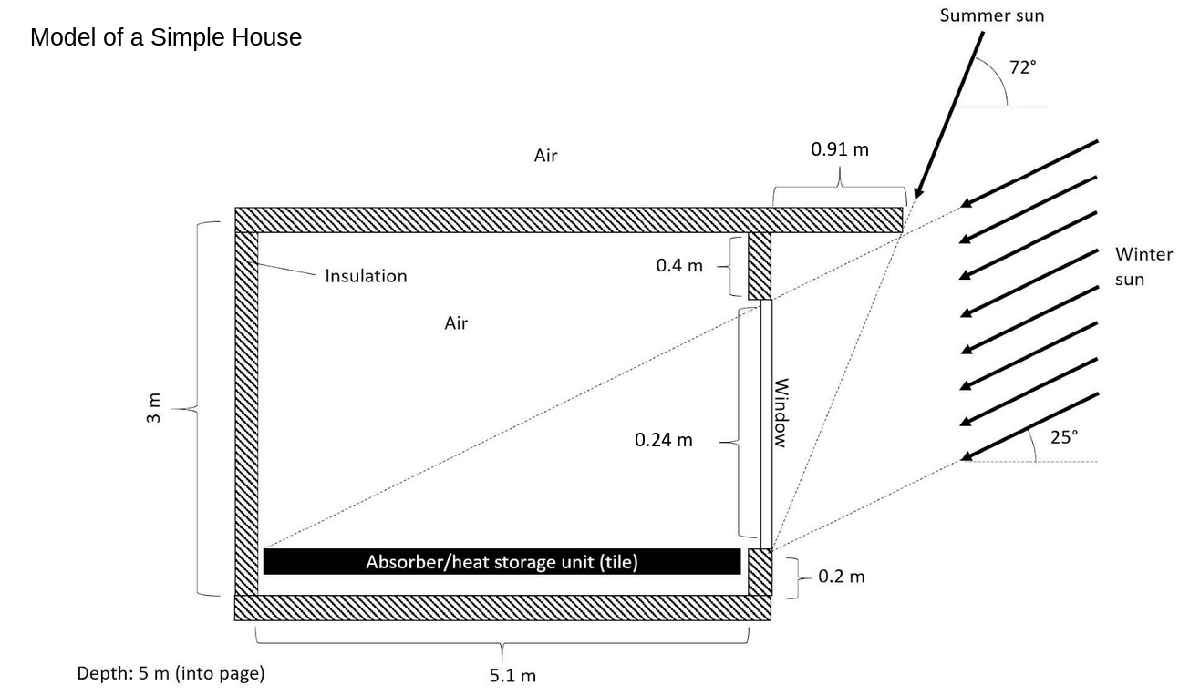

### Draw Circuit Diagram to Understand Resistance Network

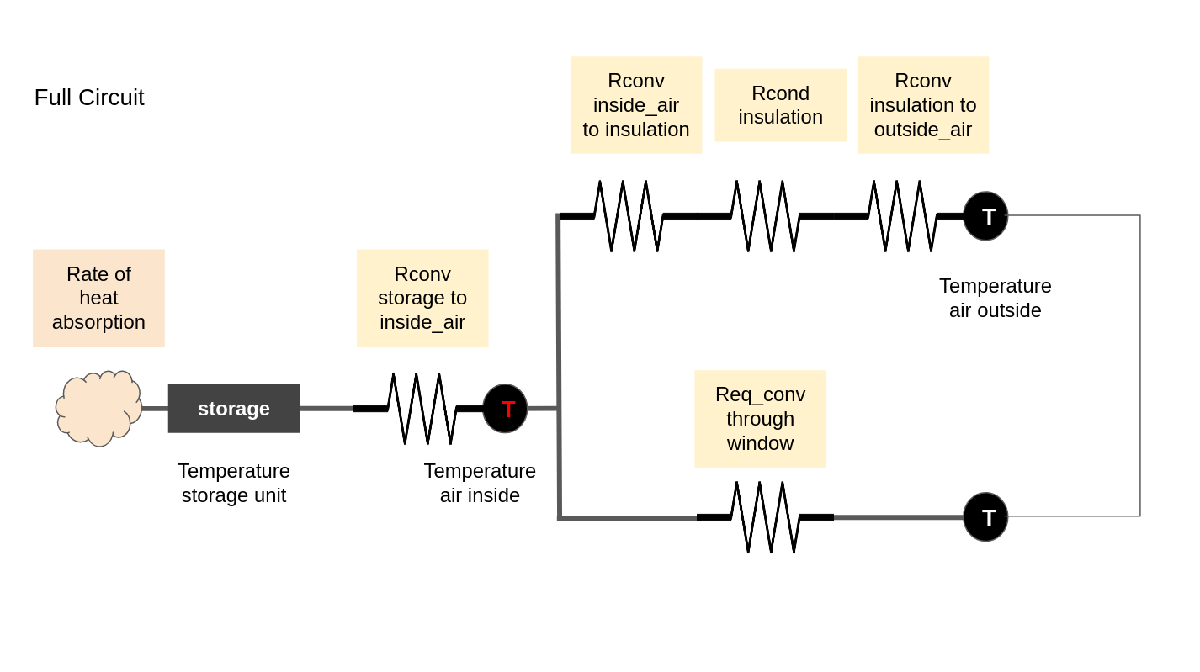

Sum resistance in series: $R_{\textrm{totseries}} =R_1 +R_2 +\;\ldotp \ldotp \ldotp +{\;R}_n$

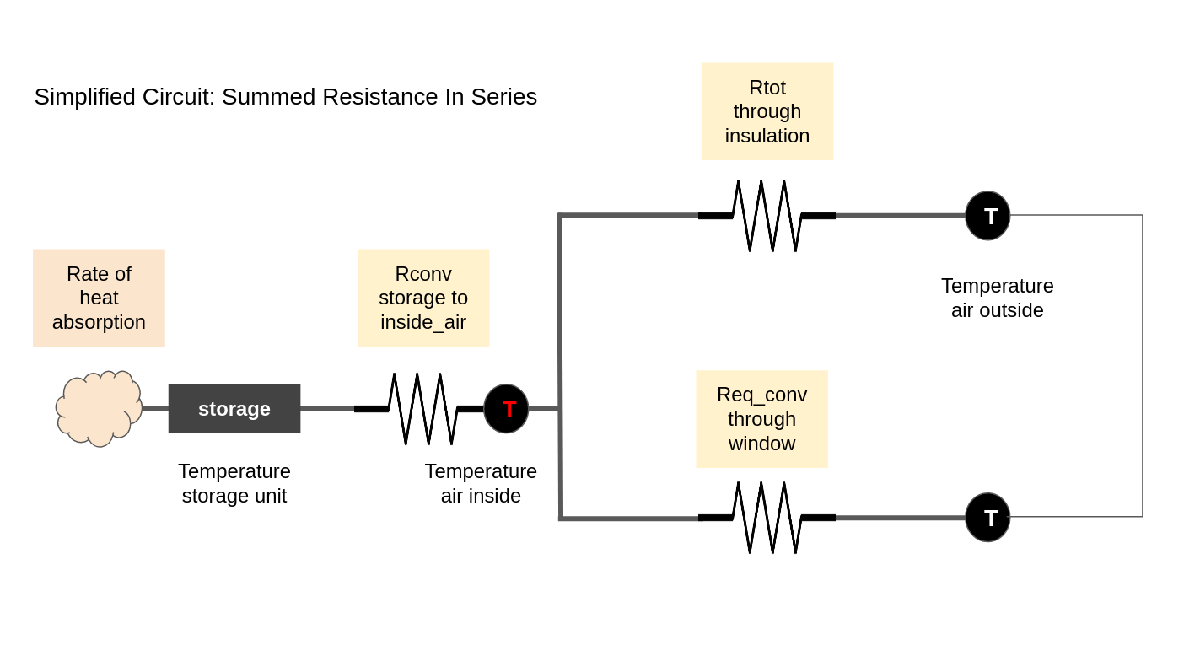

Sum the two resistances in parallel


$$R_{\textrm{totparallel}} =\frac{R_1 \;R_2 }{R_1 +R_2 }$$


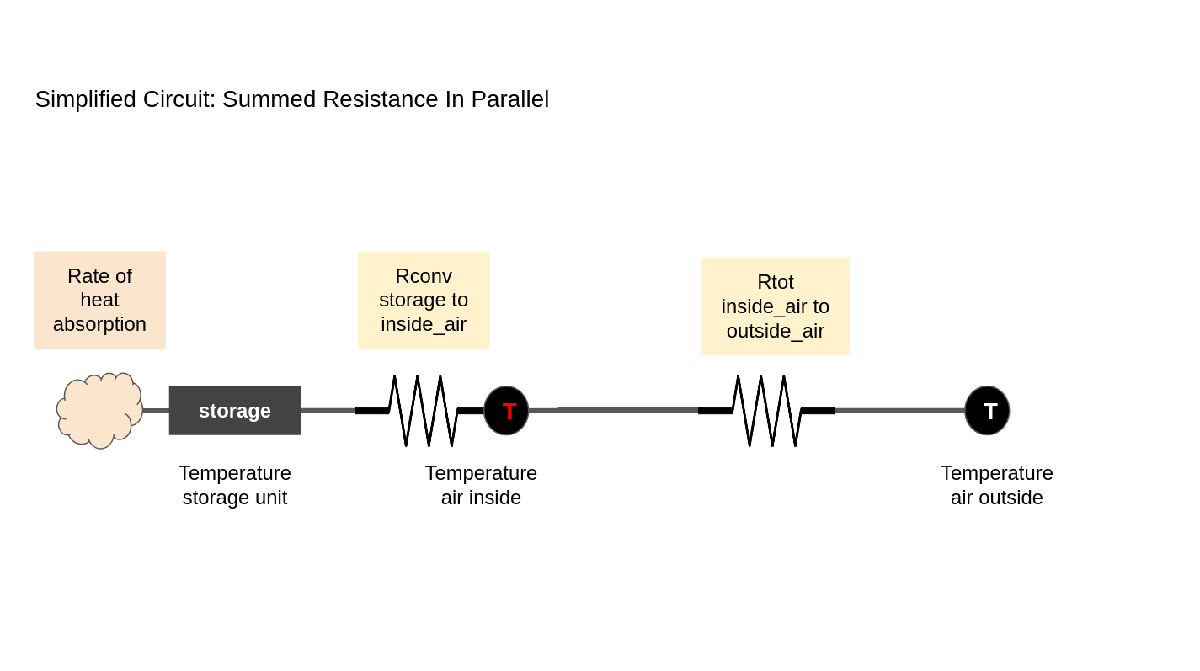

Sum in series to get resistance network in most simplified form

### 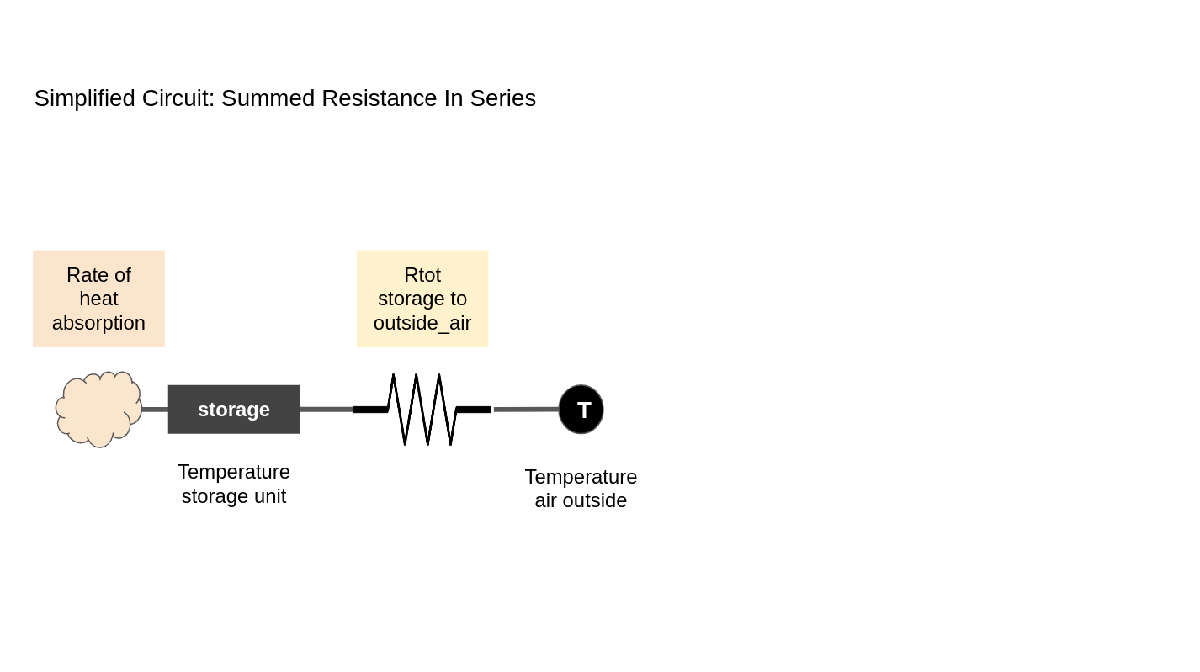

### Find a solution for the house's temperature over the course of serveral days

#### 1. Write an ordinary differential equation to model the heat storage's rate of temperature change over time.


$${\;C}_{\textrm{storage}} \frac{{\textrm{dT}}_{\textrm{storage}} }{\textrm{dt}}\;=\;\frac{{\textrm{dU}}_{\textrm{storage}} }{\textrm{dt}}\;=Q\prime_{\textrm{intostorage}} -Q\prime_{\textrm{ourofstorage}} =Q\prime_{\textrm{in}} \;-Q\prime_{\textrm{out}}$$



$$Q\prime_{\textrm{out}} =\frac{T_{\textrm{storage}\;} -T_{\textrm{outsideair}} }{R_{\textrm{totstoragetooutsideair}} }$$


final ODE for $\frac{{\textrm{dT}}_{\textrm{storage}} }{\textrm{dt}}$ is $y\prime$


$$y^{\prime } =\frac{\left(Q\prime_{\textrm{in}} -\frac{y\;-T_{\textrm{outsideair}} }{R_{\textrm{totstoragetooutsideair}} }\right)}{C_{\textrm{storage}} }$$


#### 2. Solve for $T_{\textrm{insideair}}$

Heat flow through a circuit is the same for resistors in series.


$$\frac{T_{\textrm{storage}} -T_{\textrm{outsideair}} }{R_{\textrm{totstoragetooutsideair}} }=\frac{T_{\textrm{insideair}} -T_{\textrm{outsideair}} }{R_{\textrm{totinsideairtooutsideair}} }\;$$


By rearranging


$$T_{\textrm{insideair}} ={T_{\textrm{outsideair}} \;+\;R}_{\textrm{totinsideairtooutsideair}} \frac{T_{\textrm{storage}} -T_{\textrm{outsideair}} }{R_{\textrm{totstoragetooutsideair}} }\;$$
  

#### Model With Constant vs. Sinusoidal Outside Air Temperature

tile_storage = PureThermalStorage("recycled ceramic tile", 800, 3000)

tile_storage =   PureThermalStorage with properties:

                LongName: "recycled ceramic tile"
    SpecificHeatCapacity: 800
                 Density: 3000


fiberglass_insulation = SolidPureThermalResistance("fiberglass", 0.04)

fiberglass_insulation =   SolidPureThermalResistance with properties:

               LongName: "fiberglass"
    ThermalConductivity: 0.0400


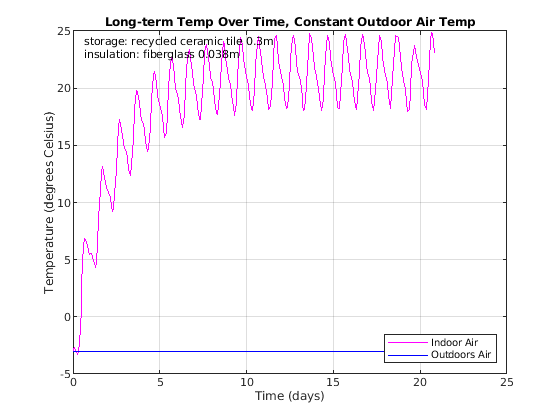

tile_storage_thickness = 0.30;
fiberglass_insulation_thickness = 0.038;

[t_days_c, T_inside_air_c] = ODEHelper(500, "constant", tile_storage_thickness, tile_storage, fiberglass_insulation_thickness, fiberglass_insulation);

#### For Model With Sinusoidal Outside Air Temperature

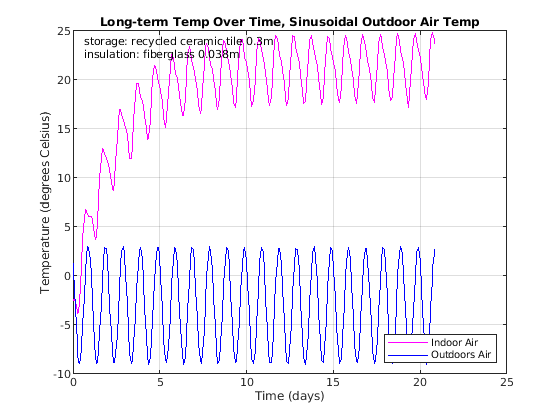

[t_days_s, T_inside_air_s] = ODEHelper(500, "sinusoidal", tile_storage_thickness, tile_storage, fiberglass_insulation_thickness, fiberglass_insulation);

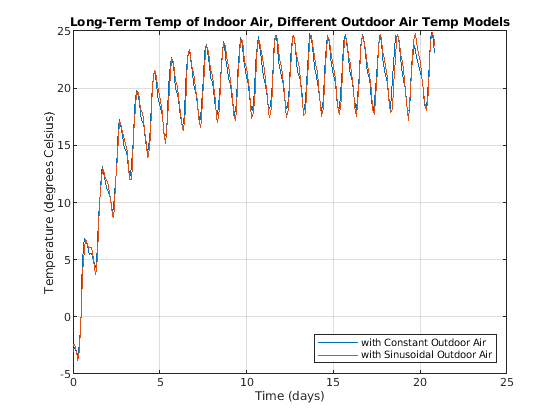

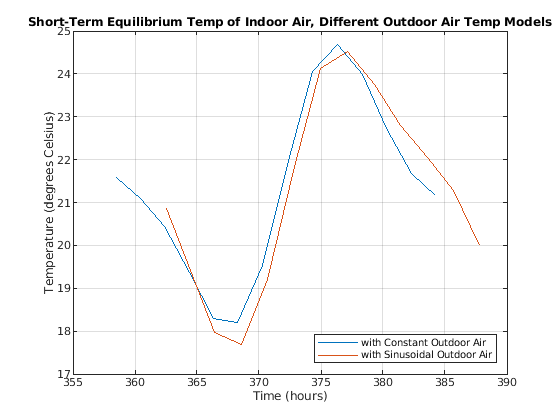

plotComparison(t_days_c, T_inside_air_c, t_days_s, T_inside_air_s);

## Optimization

Find best thickness for storage material and insulation

Compare different materials

Goal: temperature fluctuation should be between 17-25 degrees Celcius

Fiddle with: 

- Number of hours to run simulation

- storage material thickness

- insulation material thickness

- material type

masonry_storage = PureThermalStorage("masonry", 1000, 2300)

masonry_storage =   PureThermalStorage with properties:

                LongName: "masonry"
    SpecificHeatCapacity: 1000
                 Density: 2300


water_storage = PureThermalStorage("water", 4200, 1000)

water_storage =   PureThermalStorage with properties:

                LongName: "water"
    SpecificHeatCapacity: 4200
                 Density: 1000


carpet_insulation = SolidPureThermalResistance("carpet", 0.05)

carpet_insulation =   SolidPureThermalResistance with properties:

               LongName: "carpet"
    ThermalConductivity: 0.0500


gypsum_plaster_insulation = SolidPureThermalResistance("gypsum plaster", 0.5)

gypsum_plaster_insulation =   SolidPureThermalResistance with properties:

               LongName: "gypsum plaster"
    ThermalConductivity: 0.5000


aircrete_insulation = SolidPureThermalResistance("aircrete", 0.15)

aircrete_insulation =   SolidPureThermalResistance with properties:

               LongName: "aircrete"
    ThermalConductivity: 0.1500


Try out 12 Combinations and compare required thicknesses

- tile + fiberglass (base)

- tile + carpet

- tile + gypsum plaster

- tile + aircrete

- masonry  + fiberglass (base)

- masonry + carpet

- masonry + gypsum plaster

- masonry + aircrete

- water + fiberglass (base)

- water + carpet

- water + gypsum plaster

- water + aircrete

**Tests**

masonry_storage_thickness = 0.30;
water_storage_thickness = 0.15;

carpet_insulation_thickness = 0.048;
aircrete_insulation_thickness = 0.144;
gypsum_plaster_insulation_thickness = 0.485;

ODEHelper(500, "sinusoidal", tile_storage_thickness, tile_storage, fiberglass_insulation_thickness, fiberglass_insulation);

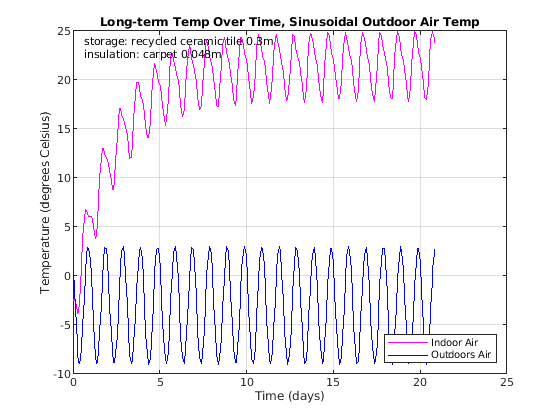

ODEHelper(500, "sinusoidal", tile_storage_thickness, tile_storage, carpet_insulation_thickness, carpet_insulation);

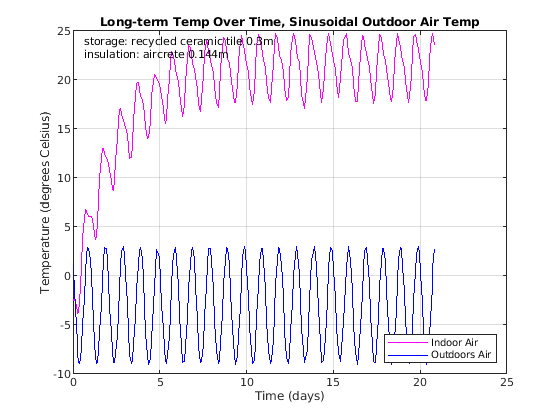

ODEHelper(500, "sinusoidal", tile_storage_thickness, tile_storage, aircrete_insulation_thickness, aircrete_insulation);

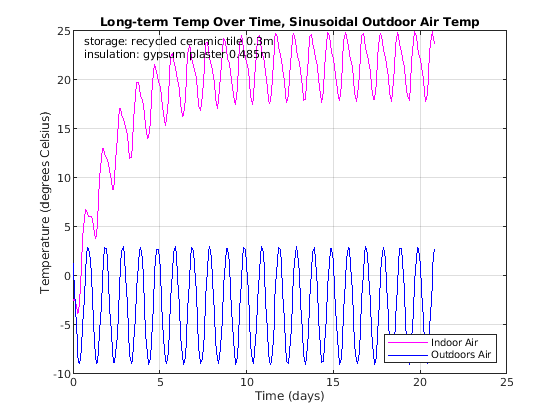

ODEHelper(500, "sinusoidal", tile_storage_thickness, tile_storage, gypsum_plaster_insulation_thickness, gypsum_plaster_insulation);

- masonry  + fiberglass

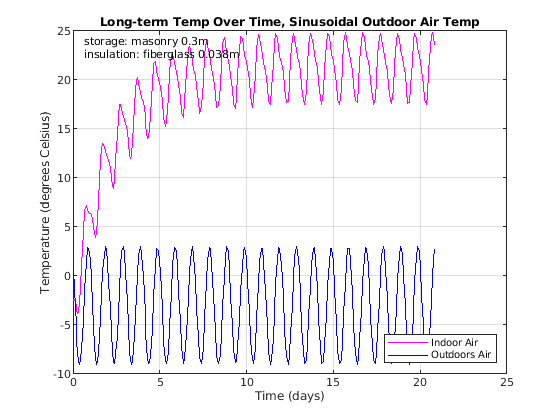

ODEHelper(500, "sinusoidal", masonry_storage_thickness, masonry_storage, fiberglass_insulation_thickness, fiberglass_insulation);

- masonry + carpet

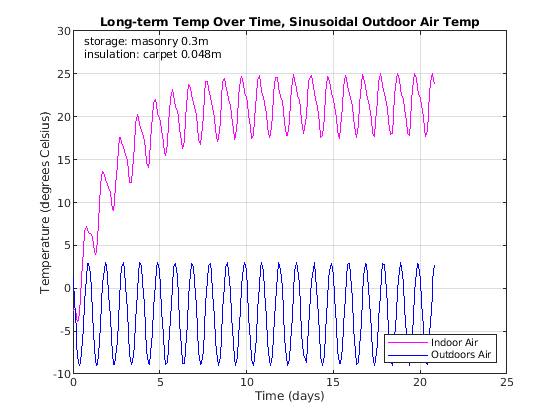

ODEHelper(500, "sinusoidal", masonry_storage_thickness, masonry_storage, carpet_insulation_thickness, carpet_insulation);

- masonry + aircrete

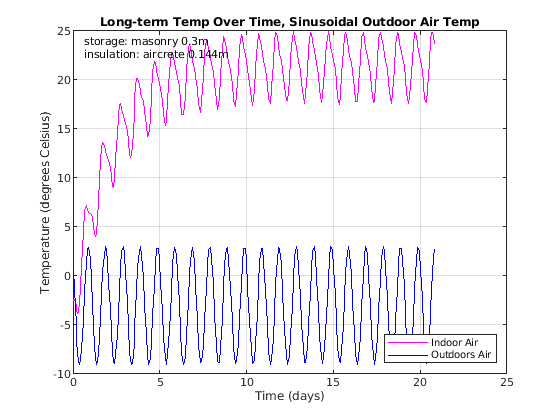

ODEHelper(500, "sinusoidal", masonry_storage_thickness, masonry_storage, aircrete_insulation_thickness, aircrete_insulation);

- masonry + gypsum plaster

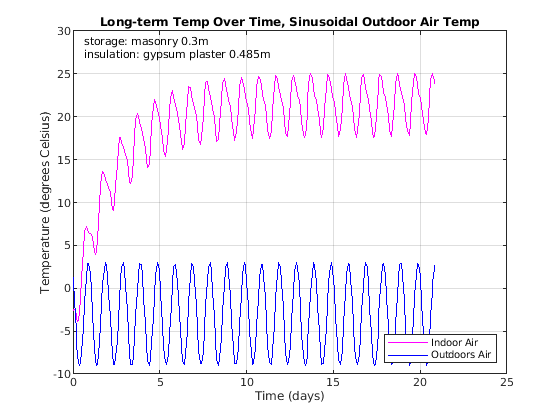

ODEHelper(500, "sinusoidal", masonry_storage_thickness, masonry_storage, gypsum_plaster_insulation_thickness, gypsum_plaster_insulation);

- water  + fiberglass

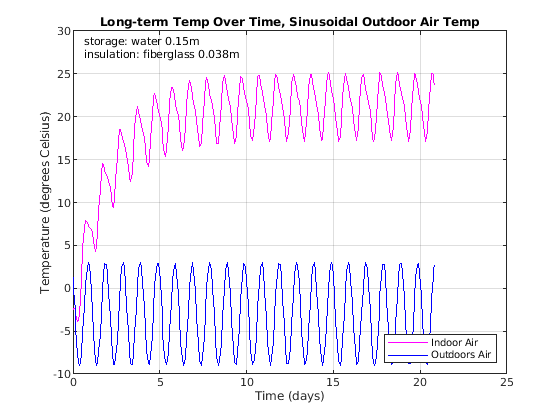

ODEHelper(500, "sinusoidal", water_storage_thickness, water_storage, fiberglass_insulation_thickness, fiberglass_insulation);

- water + carpet

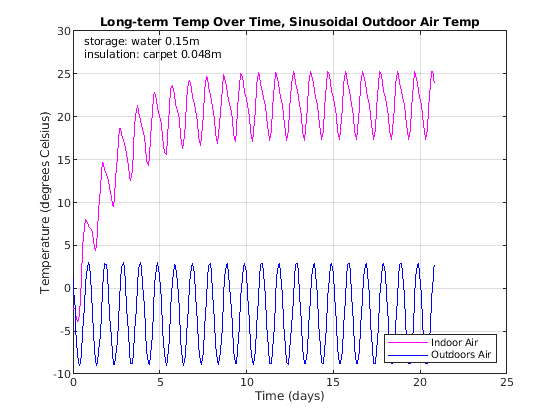

ODEHelper(500, "sinusoidal", water_storage_thickness, water_storage, carpet_insulation_thickness, carpet_insulation);

- water + aircrete

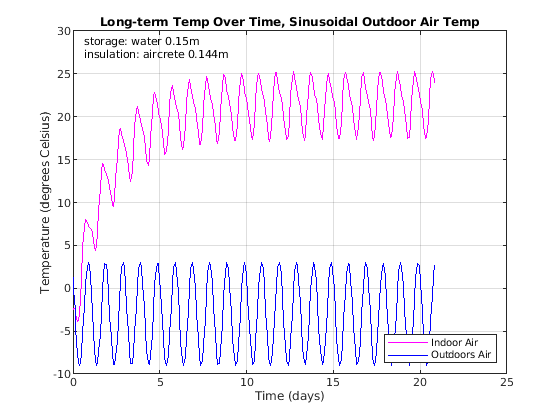

ODEHelper(500, "sinusoidal", water_storage_thickness, water_storage, 0.144, aircrete_insulation);

- water + gypsum plaster

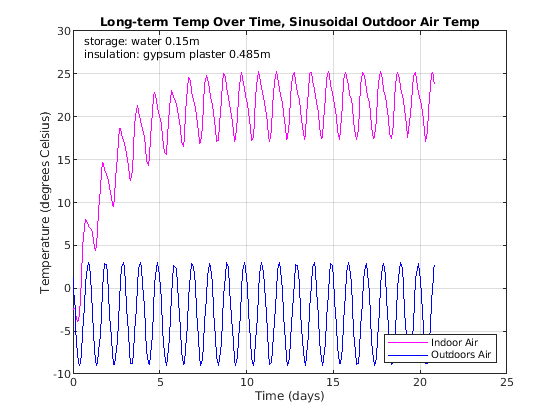

ODEHelper(500, "sinusoidal", water_storage_thickness, water_storage, gypsum_plaster_insulation_thickness, gypsum_plaster_insulation);

## Optimization Conclusions

% table of ideal thermal storage thicknesses
S.Name = [tile_storage.LongName; masonry_storage.LongName; water_storage.LongName];
S.SpecificHeatCapacity = [tile_storage.SpecificHeatCapacity; masonry_storage.SpecificHeatCapacity; water_storage.SpecificHeatCapacity];
S.Density = [tile_storage.Density; masonry_storage.Density; water_storage.Density];
S.IdealThickness = [tile_storage_thickness; masonry_storage_thickness; water_storage_thickness];
storage_table = struct2table(S)

storage_table = 3×4 table
             Name              SpecificHeatCapacity    Density    IdealThickness
    _______________________    ____________________    _______    ______________

    "recycled ceramic tile"             800             3000            0.3     
    "masonry"                          1000             2300            0.3     
    "water"                            4200             1000           0.15     


% table of idea thermal insulation thicknesses
I.Name = [fiberglass_insulation.LongName; carpet_insulation.LongName; aircrete_insulation.LongName; gypsum_plaster_insulation.LongName];
I.ThermalConductivity = [fiberglass_insulation.ThermalConductivity; carpet_insulation.ThermalConductivity; aircrete_insulation.ThermalConductivity; gypsum_plaster_insulation.ThermalConductivity];
I.IdealThickness = [fiberglass_insulation_thickness; carpet_insulation_thickness; aircrete_insulation_thickness; gypsum_plaster_insulation_thickness];
insulation_table = struct2table(I)

insulation_table = 4×3 table
          Name          ThermalConductivity    IdealThickness
    ________________    ___________________    ______________

    "fiberglass"               0.04                0.038     
    "carpet"                   0.05                0.048     
    "aircrete"                 0.15                0.144     
    "gypsum plaster"            0.5                0.485     


#### ODE Solver Helper

function [t_days, T_inside_air] = ODEHelper(t_end, air_temp_outside_model_type, storage_thickness, storage_material, insulation_thickness, insulation_material)
    % Solve ODE for the temperature of air inside model house over time
    %Input:
    %   t_end                               (number) number of hours, range of ODE
    %   air_temp_outside_model_type         (string) "sinusoidal" or (default) "constant"
    %   storage_thickness:                  (number) thickness of storage material (m)
    %   storage_material:                   (PureThermalStorage)
    %   insulation_thickness:               (number) thickness of insulation material (m)
    %   insulation_material:                (SolidPureThermalResistance)
    %Output:
    %   t_days                              (column vector) time range measured in days
    %   T_inside_air                        (column vector) temperature of inside air solved over time span

    [air_temp_outside_name, air_temp_outside_function] = air_temp_outside_model(air_temp_outside_model_type);
    
    [C_storage, Rtot_inside_air_to_outside_air, Rtot_storage_to_outside_air, b_window_area] = modelBaseHouse(storage_thickness, storage_material, insulation_thickness, insulation_material);
    yprime = @(t, y) (Qinprime(t, b_window_area) - (y - air_temp_outside_function(t)) / Rtot_storage_to_outside_air) / C_storage;
    
    % convert T_end from hours to seconds
    t_end_sec = t_end * 60 * 60;
    
    % ODE constants
    T_storage_0 = -3;
    tspan = [1 t_end_sec];
    % solve ODE for heat storage temp
    [t, y] = ode45(yprime, tspan, T_storage_0);
   
    % solve for air temp
    T_outside_air = air_temp_outside_function(t);
    T_inside_air = T_outside_air + Rtot_inside_air_to_outside_air * (y - T_outside_air) / Rtot_storage_to_outside_air;
    
    %convert t from seconds to days for readability
    t_days = t / (60 * 60 * 24);
    
    % make annotation string for readability
    annotation = {"storage: " + storage_material.LongName + " " + storage_thickness + "m" ...
        , "insulation: " + insulation_material.LongName + " " + insulation_thickness + "m"};
    
    plotHelper(annotation, "Long-term Temp Over Time, " + air_temp_outside_name, t_days, "Time (days)", y, T_inside_air, T_outside_air)    
end


#### Plotting Helpers

function [] = plotHelper(annotation, plot_title, t, t_label, ~, T_inside_air, T_outside_air)
    % Plots Heat Storage, Indoor Air, Outdoors Air over time
    figure
    plot(t, T_inside_air, 'm')
    hold on
    plot(t, T_outside_air, 'b')
    grid on
    xlabel(t_label)
    ylabel('Temperature (degrees Celsius)')
    title(plot_title)
    legend('Indoor Air', 'Outdoors Air', 'Location', 'southeast')
    
    % for easy identification
    text(0.025,0.95,annotation,'Units','normalized','FontSize',8)
    
    ax = gca;
    ax.FontSize = 8;
    hold off
end

function [t_hours_section, T_inside_air_section] = getEquilibriumIdx(t_days, T_inside_air)
    % Get index of point half-way through time span. Return section of
    % 1-day period starting half-way through time span, measured in hours
    % and degrees Celcius.
    %
    %Input:    
    %   t_days                              (column vector) time range measured in days
    %   T_inside_air                        (column vector) corresponding temperature of inside air
    %Output:
    %   t_hours_section                     (column vector) section of time range measured in hours
    %   T_inside_air_section                (column vector) corresponding section of temperature of inside air
    
    %convert t from days to hours for nice plots
    t_hours = t_days * 24;
    % find indexes of 24 hour range in equilibrium time
    % eyeball check that equilibrium was reached at least 3/4 of the way through the time span
    s = ceil(size(t_hours, 1) * (3/4));
    e = find(t_hours>t_hours(s)+24);
    e = e(1); % end 1-day period in hours
    t_hours_section = t_hours(s:e);
    T_inside_air_section = T_inside_air(s:e);
end

function [] = plotComparison(t_days_c, T_inside_air_c, t_days_s, T_inside_air_s)
    %Plot the solved indor air temperature over time for both
    %   Using a constant outdoor air temperature model
    %   Using a sinusoidal outdoor air temperature model
    
    %plot long term temp
    figure
    plot(t_days_c, T_inside_air_c)
    hold on
    grid on
    plot(t_days_s, T_inside_air_s)
    xlabel("Time (days)")
    ylabel("Temperature (degrees Celsius)")
    title("Long-Term Temp of Indoor Air, Different Outdoor Air Temp Models")
    legend("with Constant Outdoor Air", "with Sinusoidal Outdoor Air", "Location", "southeast")
    ax = gca;
    ax.FontSize = 8;
    hold off
    
    %plot temperature over course of one day at equilibrium
    [t_hours_section_c, T_inside_air_section_c] = getEquilibriumIdx(t_days_c, T_inside_air_c);
    [t_hours_section_s, T_inside_air_section_s] = getEquilibriumIdx(t_days_s, T_inside_air_s);
    figure
    plot(t_hours_section_c, T_inside_air_section_c)
    hold on
    grid on
    plot(t_hours_section_s, T_inside_air_section_s)
    xlabel("Time (hours)")
    ylabel("Temperature (degrees Celsius)")
    title("Short-Term Equilibrium Temp of Indoor Air, Different Outdoor Air Temp Models")
    legend("with Constant Outdoor Air", "with Sinusoidal Outdoor Air", "Location", "southeast")
    ax = gca;
    ax.FontSize = 8;
    hold off
end